# Market Data Cleaning Test File

**Author: Nina Matthews**

**Project: Masters Dissertation - Hierarchical portfolio stress-testing with flexible probabilities**

**Last edit: 19/12/2023**

**Supervisor: A/Prof. Tim Gebbie**

**Resources Used: **The MathWorks, Inc. (2019) 

## **Purpose**

*****

*****

*****

## **1. Environment Setup **

**Clear Env and Plots**

clc % clear command window
close all %clear all figs
clear % clears workspace

**Set Directories **

Set path to function folder

% Add /functions directory 
addpath(fullfile(userpath,'/STA5000W DISSERTATION Code/Toolboxes/dataprocessing/functions/'));

Set Image export path:

% use your default user path to create the filename and path
exportName = '';
imageExportpath = fullfile('/Users/Ninamatthews/Desktop/MASTERS/Images/Data Exploration/',exportName);

Set Processed data export path

dataExportpath = fullfile(userpath,'/STA5000W DISSERTATION Code/Data/PROCESSED/', exportName);

## 2. Data Pre-Processing

### 2.1 MARKET DATA: Load data 

fileName = "DATA-BB-MRKT-19730312-20231219.xlsx";
fileName = fullfile(userpath,'/STA5000W DISSERTATION Code/Data/BLOOMBERG/NEW MARKET',fileName);

Import per sheet and only keep certain field. importfields2keep only needed when excel has multiple sheets to import from. 

tickers2keep = {'PX_LAST'};
data_start_cell = "A7";
MARKETSheetNames = sheetnames(fileName);


MARKET_data = importfields2keep(tickers2keep,fileName,"A7");

#### 2.1.2 Clean and convert into a single timetable by synchronize dates

% Synchronize all timetable objects in the cell array
MARKET_dataTable = synchronize(MARKET_data{:});
% rename variables
MARKET_dataTable.Properties.VariableNames = MARKETSheetNames;
% Display the synchronized timetable
disp(MARKET_dataTable);

       Date        EURO_STOXX600    FTSE100    JSE_ALSI    SP_500
    ___________    _____________    _______    ________    ______

    04-Dec-1973          NaN           NaN         NaN      93.59
    05-Dec-1973          NaN           NaN         NaN      92.16
    06-Dec-1973          NaN           NaN         NaN      94.42
    07-Dec-1973          NaN           NaN         NaN      96.51
    10-Dec-1973          NaN           NaN         NaN      97.95
    11-Dec-1973          NaN           NaN         NaN      96.04
    12-Dec-1973          NaN           NaN         NaN      93.57
    13-Dec-1973          NaN           NaN         NaN      92.38
    14-Dec-1973 

When looking at the timetable we notice that there are inconsistencies with when certain signal indices are reported.  

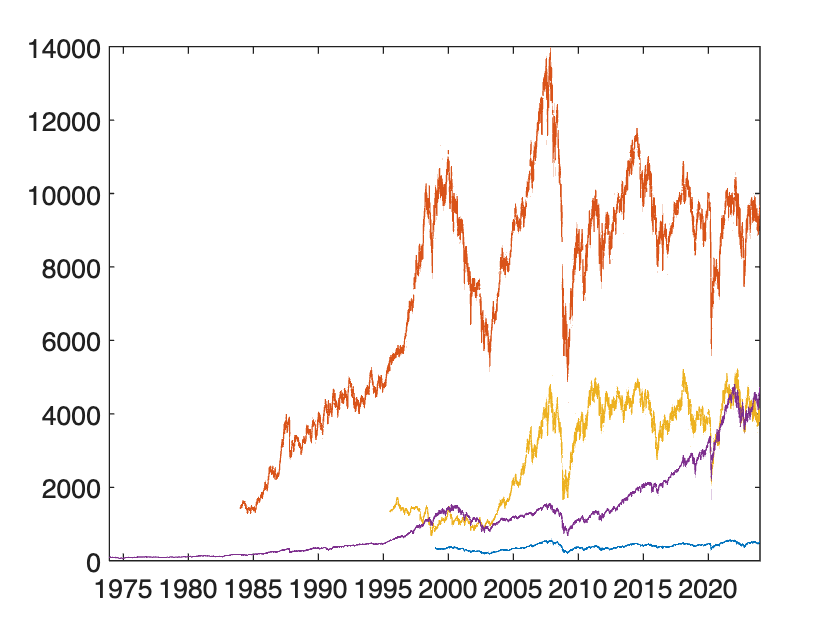

plot(MARKET_dataTable.Date,table2array(MARKET_dataTable))

% close all

**Extract the names of cols to change to valid field names (remove ' ',replace with '_')**

% rename the variables with underscores instead of spaces
newNames = strrep(MARKET_dataTable.Properties.VariableNames, ' ', '-');
MARKET_dataTable = renamevars(MARKET_dataTable, MARKET_dataTable.Properties.VariableNames, newNames);

Assign Table Properties before export:

MARKET_dataTable.Properties.Description = 'Raw Market Indicies PX_LAST Data: Market indicies prices for all major global markets. Frequency: MONTHLY. Last Updated: Dec23. Original Source: Bloomberg. Intended file naming: DATA-PROCESSED-MRK-PX_LAST-M-TTABLE-1997-2023.mat';
MARKET_dataTable.Properties.VariableDescriptions = {'Euro Stoxx600 used as European market proxy', 'JSE All Share Index used as South African market proxy',...
    'S&P 500 used as United State market proxy','FTSE100 used as United Kindom market proxy'};

**SAVE Processed MARKET Datasets:**

exportName = 'DATA-PROCESSED-MRK-PX_LAST-M-TTABLE-1997-2023.mat';
save(fullfile(dataExportpath,exportName),'MARKET_dataTable');

% Get the number of columns in the timetable
[m,n]=size(MARKET_dataTable); % size of TT
% Returns (include zero or nan for the start)
PriceChange = zeros(m,n);

% Preallocate arrays for monthly returns and geometric return series
% M_Ret_TT = timetable('RowTimes', BALFUN_TT.Dates(1:end));
M_Ret_TT = timetable('RowTimes', MARKET_dataTable.Date);

for col = 1:n
 
    index = MARKET_dataTable{:, col};  % Get the column of prices
    % Find the index of the first non-NaN value in the column
    firstNonNaNIndex = find(~isnan(index), 1, 'first');
    prices = index(firstNonNaNIndex:end);  % Get the column of prices
    
    if ~isempty(firstNonNaNIndex)
    initialPrice = prices(1);  % Get the initial price

    % Calculate the price changes
    PriceChange(firstNonNaNIndex:end,col) = 100*((prices - initialPrice) / initialPrice);
    end
end
    M_Ret_TT = array2timetable(PriceChange,'RowTimes',MARKET_dataTable.Date);


### 4.2.1 Plot Market Segment TRIs

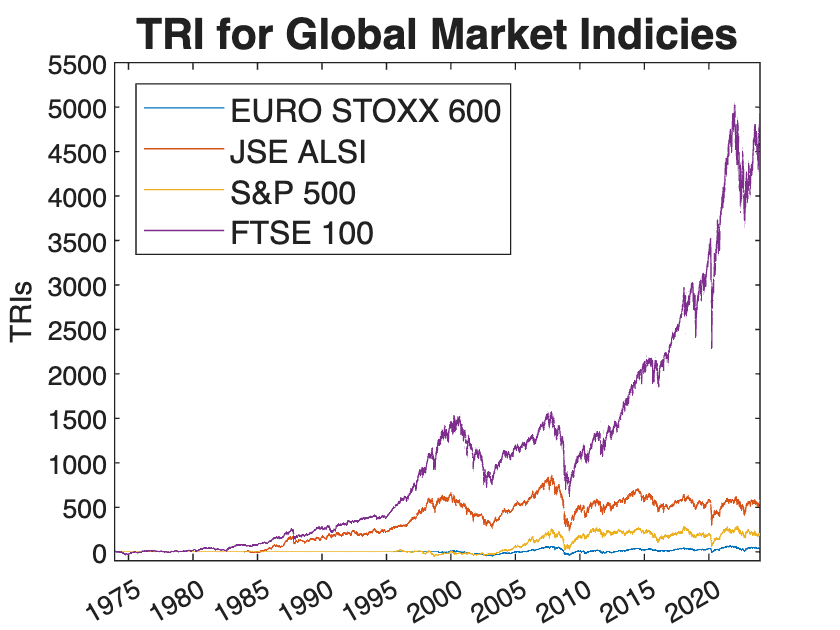

% Visualise the data on a single plot
%plot the timeseries
% Create multiple line objects using matrix input to plot
plot1 = plot(MARKET_dataTable.Date,table2array(M_Ret_TT),'LineWidth',0.5);
set(plot1(1),'DisplayName','EURO STOXX 600');
set(plot1(2),'DisplayName','JSE ALSI');
set(plot1(3),'DisplayName','S&P 500');
set(plot1(4),'DisplayName','FTSE 100');
ylabel("TRIs")
ylim([-100 5500])
% Create title
title('TRI for Global Market Indicies','FontSize',16);
datetick('x','yyyy','keeplimits')
%include the legend
% Create legend
legend1 = legend({'EURO STOXX 600','JSE ALSI','S&P 500','FTSE 100'});
set(legend1,'Location','northwest','FontSize',12);
hold off;

MARKETSEG_TRI_plot = gca;

Export Market Segment Returns plot

exportName = 'MARKETSEG_TRI_plot.pdf'
exportgraphics(MARKETSEG_TRI_plot,fullfile(imageExportpath,exportName),'Resolution',300)

#### Reference

- Lopez de Prado, Marcos. "Building diversified portfolios that outperform out-of-sample", Journal of Portfolio Management, 2016 

- [https://www.mathworks.com/help/stats/hierarchical-clustering.html](https://www.mathworks.com/help/stats/hierarchical-clustering.html)

- [https://www.mathworks.com/help/finance/asset-allocation-and-portfolio-optimization.html](https://www.mathworks.com/help/finance/asset-allocation-and-portfolio-optimization.html)